# Monte Carlo MOLI runs

Default config

%close all;
clear;
clc;
set(0,'defaultfigurecolor',[1 1 1]);

Initialize variables and set the Monte Carlo configurations

MCruns = 500;

SNR_ = zeros(MCruns,3);
noise_sig = cell(MCruns,1);
par = cell(MCruns,1);
struc = cell(MCruns,1);
J = cell(MCruns,1);

## Generate the data or load pre-saved ones

Define the number of information data

ppH = 2;
resolution = 10000;
space = 'random';
noise = 'white';
SNR = 40; %dB

W = autoGen(14);

ind = cell(length(W(:,1)),1);
for i = 1 : length(W(:,1))
if strcmp(space,'random')
    ppW = round(W(i,2)*ppH,0);
    cruze = 2*rand(ppW,1)./ppH - 1/ppH;
    i_cruze = round(cruze*resolution/W(i,2),0);
    
    ind{i} = unique(sort(abs(round(linspace(1,resolution,ppW),0) + i_cruze')));
elseif strcmp(space,'linear')
    ind{i} = unique(round(linspace(1,resolution,ppW),0)); 
end

if ind{i}(end) > resolution; ind{i}(end) = resolution; end
if ind{i}(1) <= 0; ind{i}(1) = 1; end
end

## Initialize the Monte Carlo Simulations

n_s = 1;
for mc = 1 : MCruns
    
    rng('shuffle');
    
    [dtd,dta] = alertness_sim(W,noise,SNR,resolution,ind);
    
    aux = zeros(1,4);
    for j = 1 : length(dtd.y)
        aux = [aux; dta.so{j}(ind{j},:)]; 
    end
    aux = aux(2:end,:);
    noise_sig{mc} = cell2mat(dtd.s) - aux;
    
    for i = 1 : 4
    signal = cell2mat(noise_sig);
    SNR_(mc,i) = 10*log10(sum(aux(:,i).*aux(:,i))/sum(signal(:,i).*signal(:,i)));
    end
    
    est_d = 7;
    
    dte.y = dtd.y(1:est_d); dte.t = dtd.t(1:est_d);
    dte.init = dtd.initial(1:est_d); dte.final = dtd.final(1:est_d); 
    dte.valid.y = dtd.y(est_d+1:end); dte.valid.t = dtd.t(est_d+1:end);
    dte.valid.init = dtd.initial(est_d+1:end); dte.valid.final = dtd.final(est_d+1:end);
    
    struc{mc} = struc_select('trivial',dte);
    
    par{mc} = est_regr(dte,struc{mc},'16');

    time.init = [dte.valid.t{1}(1), dte.valid.init(2:end)];
    time.final = dte.valid.final;
    initial = dte.valid.y{1}(1);
    
    dts = sim_system(par{mc},time,initial);
    
    fit = e_quad(dts,dte.valid);
     
    J{mc} = fit.quadratic;
    
    disp(['Monte Carlo run ',num2str(mc),...
                             ' Quadratic Error: ',num2str(fit.quadratic)]);
    
end

Monte Carlo run 1 Quadratic Error: 1.195
Monte Carlo run 2 Quadratic Error: 2.2372
Monte Carlo run 3 Quadratic Error: 0.91946
Monte Carlo run 4 Quadratic Error: 1.8442
Monte Carlo run 5 Quadratic Error: 0.13111
Monte Carlo run 6 Quadratic Error: 0.2097
Monte Carlo run 7 Quadratic Error: 0.068407
Monte Carlo run 8 Quadratic Error: 0.31165
Monte Carlo run 9 Quadratic Error: 0.78792
Monte Carlo run 10 Quadratic Error: 1.7804
Monte Carlo run 11 Quadratic Error: 0.00027746
Monte Carlo run 12 Quadratic Error: 4.9119
Monte Carlo run 13 Quadratic Error: 0.19415
Monte Carlo run 14 Quadratic Error: 0.039751
Monte Carlo run 15 Quadratic Error: 0.0047581
Monte Carlo run 16 Quadratic Error: 0.41183
Monte Carlo run 17 Quadratic Error: 0.33091
Monte Carlo run 18 Quadratic Error: 0.076346
Monte Carlo run 19 Quadratic Error: 2.118
Monte Carlo run 20 Quadratic Error: 0.74684
Monte Carlo run 21 Quadratic Error: 2.0976
Monte Carlo run 22 Quadratic Error: 0.99214
Monte Carlo run 23 Quadratic Error: 3.7565


## Signal to Noise Ratio Histogram

Create the histogram to prove the Signal to Noise Ratio checkout

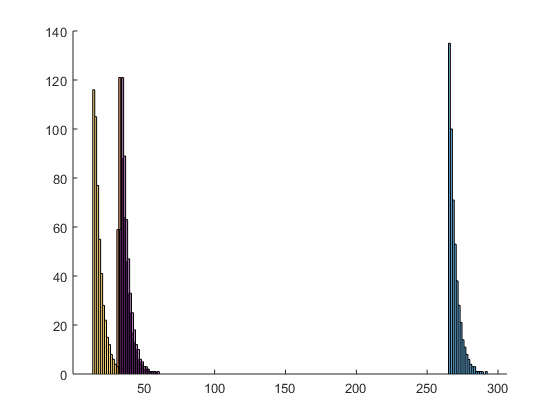

figure(8); hold on; for i = 1 : 4; histogram(SNR_(:,i),20); hold on; end

## Parameters error analisys

Determine the error for each parameter estimated at each noise realization

E = zeros(MCruns,9);

for mc = 1 : MCruns
   
   E(mc,1) = (par{mc}.est.omega - par{mc}.real.omega)/par{mc}.real.omega; 
   E(mc,2) = (par{mc}.est.tau - par{mc}.real.tau)/par{mc}.real.tau; 
   E(mc,3) = (par{mc}.est.cphase - ...
                                  par{mc}.real.cphase)/par{mc}.real.cphase;
   E(mc,4) = (par{mc}.est.M - par{mc}.real.M)/par{mc}.real.M;
   E(mc,6) = (par{mc}.est.offset - par{mc}.real.offset)/par{mc}.real.offset;
   E(mc,7) = (par{mc}.est.y_oo - par{mc}.real.y_oo)/par{mc}.real.y_oo;
   E(mc,8) = (par{mc}.est.tau_e - par{mc}.real.tau_e)/par{mc}.real.tau_e;
   
   for k = 1 : length(par{mc}.est.h0) 
       E(mc,5) = E(mc,5) + (par{mc}.est.h0(k) - par{mc}.real.h0(k))^2;
   end
   
   E(mc,5) = E(mc,5)^.5/length(par{mc}.est.h0);
   
   for k = 1 : length(par{mc}.est.h0) 
       E(mc,9) = E(mc,9) + (par{mc}.est.h0(k) + par{mc}.est.offset ...
                    - par{mc}.real.h0(k) - par{mc}.real.offset)^2;
   end
   
   E(mc,9) = E(mc,9)^.5/length(par{mc}.est.h0);    
end

E = 100.*E;

## Error test

Test the possibility of another parameter recuperation.

E_ = zeros(MCruns,2);
for mc = 1 : MCruns
   E_(mc,1) = (par{mc}.est.omega_ - par{mc}.real.omega)/par{mc}.real.omega; 
   E_(mc,2) = (par{mc}.est.tau_ - par{mc}.real.tau)/par{mc}.real.tau;  
end

E_ = 100.*E_;

## Structure errors

Determine the structure errors, such as the parameters from $B$ and $A$ matrices.

E_a = zeros(MCruns,4);
E_b = zeros(MCruns,4);
E_b1 = cell(MCruns,length(dte.y)); E_b2 = E_b1; E_b3 = E_b1; E_b4 = E_b1; 
for mc = 1 : MCruns
    
    for j = 1 : length(dte.y)
        E_b1{mc,j} = abs(par{mc}.real.struc.B{j}(1) - par{mc}.est.struc.B{j}(1))./abs(par{mc}.real.struc.B{j}(1));
        E_b2{mc,j} = abs(par{mc}.real.struc.B{j}(2) - par{mc}.est.struc.B{j}(2))./abs(par{mc}.real.struc.B{j}(2));
        E_b3{mc,j} = abs(par{mc}.real.struc.B{j}(3) - par{mc}.est.struc.B{j}(3))./abs(par{mc}.real.struc.B{j}(3));
        E_b4{mc,j} = abs(par{mc}.real.struc.B{j}(4) - par{mc}.est.struc.B{j}(4))./abs(par{mc}.real.struc.B{j}(4));
    end
    
    for i = 1 : 4
        if i == 1
            E_a(mc,i) = par{mc}.real.struc.A(i,4)...
                            - par{mc}.est.struc.A(i,4);
        else
            E_a(mc,i) = (par{mc}.real.struc.A(i,4)...
                            - par{mc}.est.struc.A(i,4))./...
                                    abs(par{mc}.real.struc.A(i,4));
        end
    end
end

## Plotting parameters error results

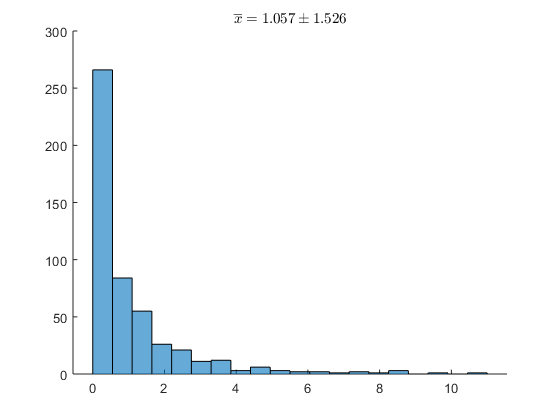

figure(9); hold on;
histogram(cell2mat(J),20);
title(['$$\overline{x} =',num2str(round(mean(cell2mat(J)),3)),...
     '\pm',num2str(round(std(cell2mat(J)),3)),'$$'],'Interpreter','latex');

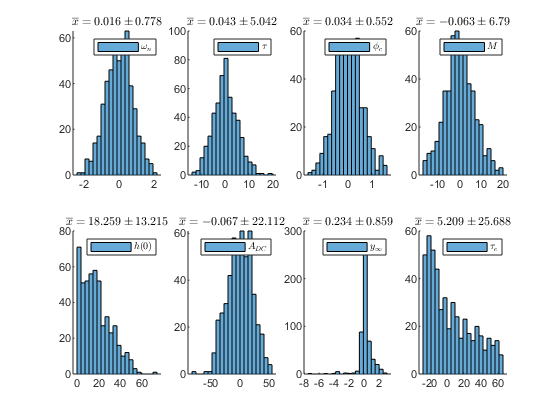


figure(10); hold on;
for k = 1 : 8
    subplot(2,4,k); hold on;
    histogram(E(:,k),20); hold on;
    title(['$$\overline{x} =',num2str(round(mean(E(:,k)),3)),...
          '\pm',num2str(round(std(E(:,k)),3)),'$$'],'Interpreter','latex');
    leg = par{1}.TexNames{k};
    %xlim([-100,100]);
    legend([{leg}],'Interpreter','latex'); hold off;
end

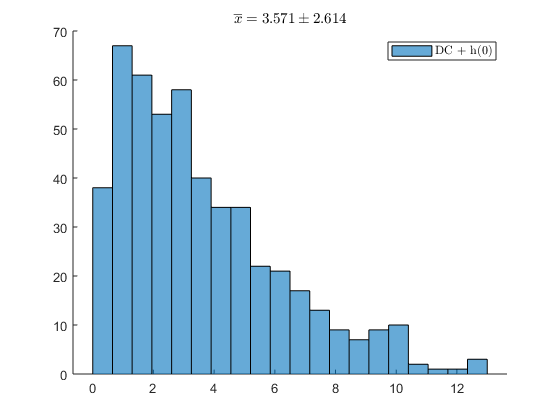


figure(11); hold on;
histogram(E(:,9),20); hold on;
title(['$$\overline{x} =',num2str(round(mean(E(:,9)),3)),...
         '\pm',num2str(round(std(E(:,9)),3)),'$$'],'Interpreter','latex');
leg = 'DC + h(0)';
%xlim([-100,100]);
legend([{leg}],'Interpreter','latex'); hold off;

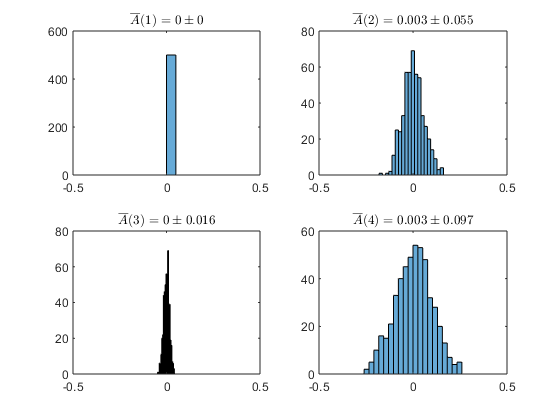


figure(12); hold on;
for i = 1 : 4
    subplot(2,2,i); 
    histogram(E_a(:,i),20); hold on;
    title(['$$\overline{A}(',num2str(i),') =',...
            num2str(round(mean(E_a(:,i)),3)),'\pm',...
             num2str(round(std(E_a(:,i)),3)),'$$'],'Interpreter','latex');
    xlim([-.5,.5]); hold off; 
end

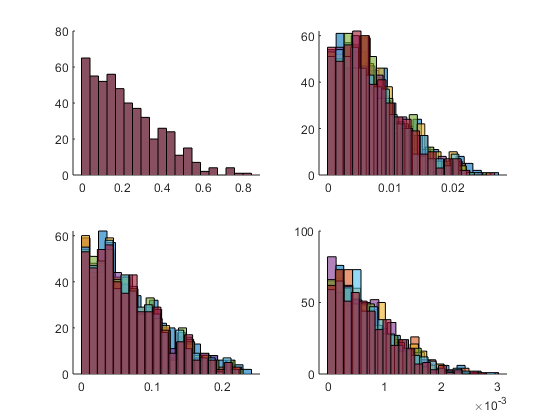


figure(13); hold on;

subplot(2,2,1); hold on;
error = cell2mat(E_b1);
for w = 1 : length(dte.y)
    histogram(error(:,w),20); hold on;
end

subplot(2,2,2); hold on;
error = cell2mat(E_b2);
for w = 1 : length(dte.y)
    histogram(error(:,w),20); hold on;
end

subplot(2,2,3); hold on;
error = cell2mat(E_b3);
for w = 1 : length(dte.y)
    histogram(error(:,w),20); hold on;
end

subplot(2,2,4); hold on;
error = cell2mat(E_b4);
for w = 1 : length(dte.y)
    histogram(error(:,w),20); hold on;
end
hold off;

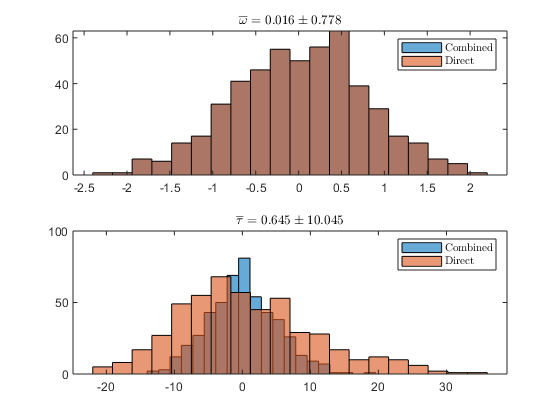


figure(14); hold on;
subplot(2,1,1);
histogram(E_(:,1),20); hold on;
histogram(E(:,1),20); hold on;
title(['$$\overline{\omega} =',num2str(round(mean(E_(:,1)),3)),...
      '\pm',num2str(round(std(E_(:,1)),3)),'$$'],'Interpreter','latex');
legend([{'Combined'},{'Direct'}],'Interpreter','latex'); hold off;

subplot(2,1,2);
histogram(E(:,2),20); hold on;
histogram(E_(:,2),20); hold on;
title(['$$\overline{\tau} =',num2str(round(mean(E_(:,2)),3)),...
       '\pm',num2str(round(std(E_(:,2)),3)),'$$'],'Interpreter','latex');
legend([{'Combined'},{'Direct'}],'Interpreter','latex'); hold off;